% Initializing script
clc, clf, clear

% Reference motor values
P_c_ref = 206.429E+05;  % chamber pressure (Pa)
A_t_ref = 0.0602;   % throat area (m2)
A_e_ref = 4.1548;   % exit area (m2)

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i), A_t_ref, A_e_ref]);
    total_mass_A_t(i) = calc_objective([P_c_ref, A_t(i), A_e_ref]);
    total_mass_A_e(i) = calc_objective([P_c_ref, A_t_ref, A_e(i)]);
end

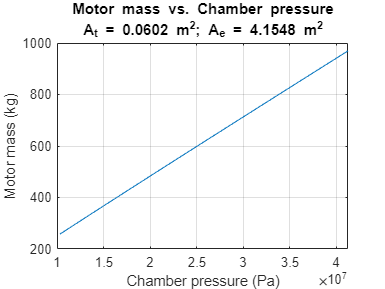

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

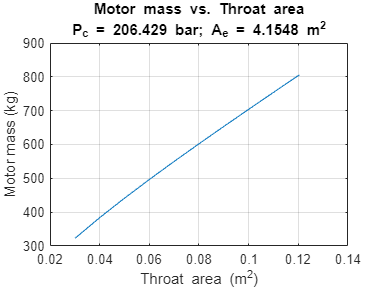


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

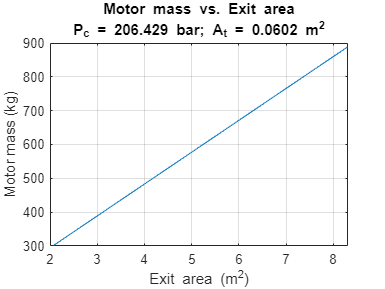


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            total_mass_val(i, j, k) = calc_objective([P_c(i), A_t(j), A_e(k)]);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints([P_c(i), A_t(j), A_e(k)]);
        end
    end
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

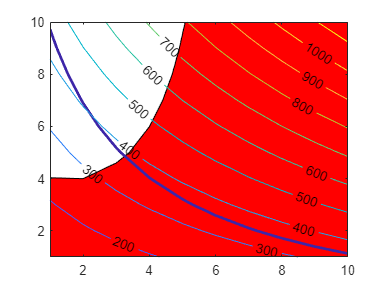

% Example plot
clf
i = 2;
contourf(ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(total_mass_val(:, :, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [P_c(1), A_t(1), A_e(1)];
ub = [P_c(length(P_c)), A_t(length(A_t)), A_e(length(A_e))];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');

for i = 2:7
    x0 = [P_c(i), A_t(i), A_e(i)]
    [x, fval, exitflag, output, lambda] = fmincon(@calc_objective, x0, ...
        A, b, Aeq, beq, lb, ub, @calc_constraints, options)
    fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f', x(1), x(2), x(3))
end

x0 = 1.0e+07 *

    1.3762    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    2.3844    0.0000    0.0000


fval = 372.6658

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 42
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.964166e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.110223e-16, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.1102e-16
           stepsize: 4.5303e-04
       lssteplength: 1
      firstorderopt: 1.9563e-05
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 529.8947
       ineqlin: [0×1 double]
    ineqnonlin: 1.1509e+04
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 23844066.351063
Throat area = 0.052130
Exit area = 2.691698

x0 = 1.0e+07 *

    1.7202    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    2.6759    0.0000    0.0000


fval = 329.0381

exitflag = 1

output = struct with fields:
         iterations: 5
          funcCount: 25
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.348095e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 2.775558e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 2.7756e-15
           stepsize: 0.9299
       lssteplength: 1
      firstorderopt: 1.1681e-05
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 464.4531
       ineqlin: [0×1 double]
    ineqnonlin: 7.7589e+03
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 26759341.115885
Throat area = 0.046451
Exit area = 2.174964

x0 = 1.0e+07 *

    2.0643    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    2.0643    0.0000    0.0000


fval = 497.7894

exitflag = 1

output = struct with fields:
         iterations: 2
          funcCount: 12
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.340505e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.665335e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.6653e-15
           stepsize: 0.0013
       lssteplength: 1
      firstorderopt: 3.4330e-04
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 717.5815
       ineqlin: [0×1 double]
    ineqnonlin: 5.9853e+04
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 20642900.001440
Throat area = 0.060214
Exit area = 4.154765

x0 = 1.0e+07 *

    2.4083    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    2.4083    0.0000    0.0000


fval = 368.1085

exitflag = 1

output = struct with fields:
         iterations: 5
          funcCount: 24
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.681132e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 2.362888e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 2.3629e-12
           stepsize: 3.0026e-05
       lssteplength: 1
      firstorderopt: 8.2923e-05
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 523.0586
       ineqlin: [0×1 double]
    ineqnonlin: 1.1026e+04
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 24083383.333397
Throat area = 0.051612
Exit area = 2.637430

x0 = 1.0e+07 *

    2.7524    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    2.7524    0.0000    0.0000


fval = 320.7317

exitflag = 1

output = struct with fields:
         iterations: 3
          funcCount: 16
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 6.130382e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 2.331468e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 2.3315e-15
           stepsize: 2.4362e-06
       lssteplength: 1
      firstorderopt: 3.0669e-04
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 232.7850
       ineqlin: [0×1 double]
    ineqnonlin: 0
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 27523866.666651
Throat area = 0.045160
Exit area = 2.077400

x0 = 1.0e+07 *

    3.0964    0.0000    0.0000



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x = 1.0e+07 *

    3.0964    0.0000    0.0000


fval = 329.2763

exitflag = 1

output = struct with fields:
         iterations: 3
          funcCount: 16
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.648676e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 6.953239e-16, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 8.8818e-16
           stepsize: 2.5194e-06
       lssteplength: 1
      firstorderopt: 9.3305e-05
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 232.3396
       ineqlin: [0×1 double]
    ineqnonlin: 0
         lower: [3×1 double]
         upper: [3×1 double]


Chamber pressure = 30964349.999982
Throat area = 0.039913
Exit area = 2.077400